# Load CSV Measurement Data

clear all;
for k=1:1:6
    filename = sprintf('%s_%d','DD6_Y_300',k)
    angesteuerteRichtung="x"; %hier angeben welche Ricktung (x,y,theta) angesteurt wurde. Benoetigt, um unten automatisch cov() zu berechnen.
    
    %Zu importierende Datei auswählen
    %filename = "DD6_THETA_1_2"
    %filename = "DC8/varTheta3DC8_1";
    %Importieren und nicht relevante Informationen entfernen
    data = readtable(filename);
    data = data(6:height(data)-1,:);
    
    taskTime = 10e-3; %10ms
    

filename = 'DD6_Y_300_1'

filename = 'DD6_Y_300_2'

filename = 'DD6_Y_300_3'

filename = 'DD6_Y_300_4'

filename = 'DD6_Y_300_5'

filename = 'DD6_Y_300_6'

## Encoderdaten filtern

## optional: Plotten der Odometrie

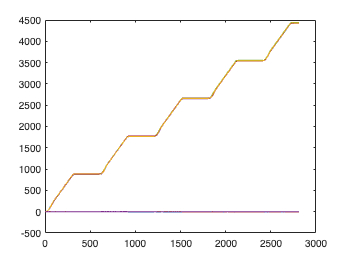

    % Plot x-Koordinatenverlauf nach Odomterie
    distX=data(:,"distX");
    distX=table2array(distX);
    plot(distX); hold on;

    
    plot(table2array(data(:,"distY")));
    plot(table2array(data(:,"distTheta")));
    %legend("distX","Odometrie xTf","Kamera x");
    %legend("distX","xOdo");
    %legend("xOdo");
    

## Umschaltpunkte ermitteln

    % In diesem Abschnitt werden die Indizes ermittelt zu denen die
    % ST-StateMachine ihren State verändert hat. In state 0 wartet der Robob 2
    % sec nach statren des task mit dem losfahren. Bei State 1 wird dann die
    % geschwindigkeit v=vsoll gesetzt und der Robo faehrt 2 sec. state 2 v=0
    % fuer 2sec. state 3 v=vsoll fuer 2 sec. state 4 v=0.
    stateOld=0;
    stateChange =zeros(11,1);
    
    for row = 1 : height(data)
        state = data{row,"state"};
        if state ~= stateOld
            stateChange(state)=row
            stateOld = state;
        end
    end

stateChange =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange =            1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange =      1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange =      1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange =            1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange =            1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
     1
     0
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
     0
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
     0
     0
     0
     0
     0
     0
     0


stateChange = 11×1
     1
   302
   603
   904
     0
     0
     0
     0
     0
     0


stateChange = 11×1
           1
         302
         603
         904
        1205
           0
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
           0
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
           0
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
           0
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
           0


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


stateChange = 11×1
           1
         302
         603
         904
        1205
        1506
        1807
        2108
        2409
        2710


## Berechnen der zurueckgelegten Strecken je Ansteuerung

    % In diesem Abschnitt wird anhand der zuvor berechneten Odometrie ermittelt
    % welche Strecke der Robo zurueckgelegt hat und welche er haette
    % zurücklegen sollen
    xDiffIntervall = zeros(5,1);
    yDiffIntervall = zeros(5,1);
    thetaDiffIntervall =zeros(5,1);
    
    xDiffIntervall(1) = data{stateChange(2), "distX"}

xDiffIntervall =     0.9609
         0
         0
         0
         0


xDiffIntervall = 5×1
    1.6916
         0
         0
         0
         0


xDiffIntervall = 5×1
   -0.3011
         0
         0
         0
         0


xDiffIntervall = 5×1
    1.1602
         0
         0
         0
         0


xDiffIntervall = 5×1
   -0.4163
         0
         0
         0
         0


xDiffIntervall = 5×1
   -0.3144
         0
         0
         0
         0


    yDiffIntervall(1) = data{stateChange(2), "distY"}

yDiffIntervall =   847.7059
         0
         0
         0
         0


yDiffIntervall = 5×1
  857.3010
         0
         0
         0
         0


yDiffIntervall = 5×1
  853.9824
         0
         0
         0
         0


yDiffIntervall = 5×1
  839.7982
         0
         0
         0
         0


yDiffIntervall = 5×1
  856.8714
         0
         0
         0
         0


yDiffIntervall = 5×1
  851.8886
         0
         0
         0
         0


    thetaDiffIntervall(1) = data{stateChange(2),"distTheta"}

thetaDiffIntervall =     0.0746
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0208
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0519
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0411
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0411
         0
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0534
         0
         0
         0
         0


    
    for i=2 : length(stateChange)-1
        xDiffIntervall(i) = data{stateChange(i+1), "distX"} - data{stateChange(i), "distX"}
        yDiffIntervall(i) = data{stateChange(i+1), "distY"} - data{stateChange(i), "distY"}
        thetaDiffIntervall(i) = data{stateChange(i+1), "distTheta"} - data{stateChange(i), "distTheta"}
    end

xDiffIntervall =     0.9609
   -2.1698
         0
         0
         0


yDiffIntervall =   847.7059
   35.0310
         0
         0
         0


thetaDiffIntervall =     0.0746
   -0.0409
         0
         0
         0


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
         0
         0


yDiffIntervall =   847.7059
   35.0310
  855.7235
         0
         0


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
         0
         0


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
         0


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
         0


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
         0


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480
   -0.5491


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508
   31.7483


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342
   -0.0296


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480
   -0.5491
    1.4170


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508
   31.7483
  856.9942


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342
   -0.0296
    0.0404


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480
   -0.5491
    1.4170
   -1.7934


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508
   31.7483
  856.9942
   29.1124


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342
   -0.0296
    0.0404
   -0.0179


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480
   -0.5491
    1.4170
   -1.7934
    2.1211


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508
   31.7483
  856.9942
   29.1124
  852.8345


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342
   -0.0296
    0.0404
   -0.0179
    0.0548


xDiffIntervall =     0.9609
   -2.1698
   -2.0768
   -2.2407
   -0.2480
   -0.5491
    1.4170
   -1.7934
    2.1211
   -0.7749


yDiffIntervall =   847.7059
   35.0310
  855.7235
   30.9711
  859.5508
   31.7483
  856.9942
   29.1124
  852.8345
   31.3162


thetaDiffIntervall =     0.0746
   -0.0409
   -0.0090
   -0.0137
    0.0342
   -0.0296
    0.0404
   -0.0179
    0.0548
   -0.0262


xDiffIntervall = 5×1
    1.6916
   -1.9838
         0
         0
         0


yDiffIntervall = 5×1
  857.3010
   33.3896
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0208
   -0.0173
         0
         0
         0


xDiffIntervall = 5×1
    1.6916
   -1.9838
    2.3957
         0
         0


yDiffIntervall = 5×1
  857.3010
   33.3896
  854.1282
         0
         0


thetaDiffIntervall = 5×1
    0.0208
   -0.0173
    0.0410
         0
         0


xDiffIntervall = 5×1
    1.6916
   -1.9838
    2.3957
   -2.9049
         0


yDiffIntervall = 5×1
  857.3010
   33.3896
  854.1282
   34.7600
         0


thetaDiffIntervall = 5×1
    0.0208
   -0.0173
    0.0410
   -0.0457
         0


xDiffIntervall = 5×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517


yDiffIntervall = 5×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012


thetaDiffIntervall = 5×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265


xDiffIntervall = 6×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517
   -3.2105


yDiffIntervall = 6×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012
   31.5105


thetaDiffIntervall = 6×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265
   -0.0302


xDiffIntervall = 7×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517
   -3.2105
    2.1477


yDiffIntervall = 7×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012
   31.5105
  855.2684


thetaDiffIntervall = 7×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265
   -0.0302
    0.0352


xDiffIntervall = 8×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517
   -3.2105
    2.1477
   -4.4681


yDiffIntervall = 8×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012
   31.5105
  855.2684
   31.8582


thetaDiffIntervall = 8×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265
   -0.0302
    0.0352
   -0.0225


xDiffIntervall = 9×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517
   -3.2105
    2.1477
   -4.4681
    2.6569


yDiffIntervall = 9×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012
   31.5105
  855.2684
   31.8582
  856.6874


thetaDiffIntervall = 9×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265
   -0.0302
    0.0352
   -0.0225
    0.0418


xDiffIntervall = 10×1
    1.6916
   -1.9838
    2.3957
   -2.9049
    1.6517
   -3.2105
    2.1477
   -4.4681
    2.6569
   -2.1521


yDiffIntervall = 10×1
  857.3010
   33.3896
  854.1282
   34.7600
  858.1012
   31.5105
  855.2684
   31.8582
  856.6874
   28.9155


thetaDiffIntervall = 10×1
    0.0208
   -0.0173
    0.0410
   -0.0457
    0.0265
   -0.0302
    0.0352
   -0.0225
    0.0418
   -0.0150


xDiffIntervall = 5×1
   -0.3011
   -3.5559
         0
         0
         0


yDiffIntervall = 5×1
  853.9824
   34.5836
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0519
   -0.0250
         0
         0
         0


xDiffIntervall = 5×1
   -0.3011
   -3.5559
    2.7588
         0
         0


yDiffIntervall = 5×1
  853.9824
   34.5836
  853.6220
         0
         0


thetaDiffIntervall = 5×1
    0.0519
   -0.0250
    0.0265
         0
         0


xDiffIntervall = 5×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
         0


yDiffIntervall = 5×1
  853.9824
   34.5836
  853.6220
   33.8115
         0


thetaDiffIntervall = 5×1
    0.0519
   -0.0250
    0.0265
   -0.0294
         0


xDiffIntervall = 5×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026


yDiffIntervall = 5×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646


thetaDiffIntervall = 5×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478


xDiffIntervall = 6×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026
   -3.6666


yDiffIntervall = 6×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646
   33.8345


thetaDiffIntervall = 6×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478
   -0.0286


xDiffIntervall = 7×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026
   -3.6666
   -0.8236


yDiffIntervall = 7×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646
   33.8345
  849.0737


thetaDiffIntervall = 7×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478
   -0.0286
    0.0554


xDiffIntervall = 8×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026
   -3.6666
   -0.8236
   -1.4525


yDiffIntervall = 8×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646
   33.8345
  849.0737
   31.2012


thetaDiffIntervall = 8×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478
   -0.0286
    0.0554
   -0.0269


xDiffIntervall = 9×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026
   -3.6666
   -0.8236
   -1.4525
    0.8148


yDiffIntervall = 9×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646
   33.8345
  849.0737
   31.2012
  848.5419


thetaDiffIntervall = 9×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478
   -0.0286
    0.0554
   -0.0269
    0.0658


xDiffIntervall = 10×1
   -0.3011
   -3.5559
    2.7588
   -1.8731
    1.1026
   -3.6666
   -0.8236
   -1.4525
    0.8148
   -1.5322


yDiffIntervall = 10×1
  853.9824
   34.5836
  853.6220
   33.8115
  853.0646
   33.8345
  849.0737
   31.2012
  848.5419
   31.5540


thetaDiffIntervall = 10×1
    0.0519
   -0.0250
    0.0265
   -0.0294
    0.0478
   -0.0286
    0.0554
   -0.0269
    0.0658
   -0.0202


xDiffIntervall = 5×1
    1.1602
   -1.2000
         0
         0
         0


yDiffIntervall = 5×1
  839.7982
   34.6807
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0270
         0
         0
         0


xDiffIntervall = 5×1
    1.1602
   -1.2000
    0.8015
         0
         0


yDiffIntervall = 5×1
  839.7982
   34.6807
  858.7455
         0
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0270
    0.0309
         0
         0


xDiffIntervall = 5×1
    1.1602
   -1.2000
    0.8015
    0.1461
         0


yDiffIntervall = 5×1
  839.7982
   34.6807
  858.7455
   29.3067
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0270
    0.0309
   -0.0355
         0


xDiffIntervall = 5×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362


yDiffIntervall = 5×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547


thetaDiffIntervall = 5×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285


xDiffIntervall = 6×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362
   -2.6481


yDiffIntervall = 6×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547
   30.8586


thetaDiffIntervall = 6×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285
   -0.0207


xDiffIntervall = 7×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362
   -2.6481
    1.0893


yDiffIntervall = 7×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547
   30.8586
  858.6457


thetaDiffIntervall = 7×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285
   -0.0207
    0.0362


xDiffIntervall = 8×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362
   -2.6481
    1.0893
   -2.6968


yDiffIntervall = 8×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547
   30.8586
  858.6457
   29.7874


thetaDiffIntervall = 8×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285
   -0.0207
    0.0362
   -0.0179


xDiffIntervall = 9×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362
   -2.6481
    1.0893
   -2.6968
    0.0664


yDiffIntervall = 9×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547
   30.8586
  858.6457
   29.7874
  854.0310


thetaDiffIntervall = 9×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285
   -0.0207
    0.0362
   -0.0179
    0.0472


xDiffIntervall = 10×1
    1.1602
   -1.2000
    0.8015
    0.1461
    1.0362
   -2.6481
    1.0893
   -2.6968
    0.0664
   -3.2725


yDiffIntervall = 10×1
  839.7982
   34.6807
  858.7455
   29.3067
  860.8547
   30.8586
  858.6457
   29.7874
  854.0310
   32.2008


thetaDiffIntervall = 10×1
    0.0411
   -0.0270
    0.0309
   -0.0355
    0.0285
   -0.0207
    0.0362
   -0.0179
    0.0472
   -0.0238


xDiffIntervall = 5×1
   -0.4163
   -2.2717
         0
         0
         0


yDiffIntervall = 5×1
  856.8714
   31.7764
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0320
         0
         0
         0


xDiffIntervall = 5×1
   -0.4163
   -2.2717
    3.1352
         0
         0


yDiffIntervall = 5×1
  856.8714
   31.7764
  854.2228
         0
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0320
    0.0329
         0
         0


xDiffIntervall = 5×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
         0


yDiffIntervall = 5×1
  856.8714
   31.7764
  854.2228
   31.8378
         0


thetaDiffIntervall = 5×1
    0.0411
   -0.0320
    0.0329
   -0.0199
         0


xDiffIntervall = 5×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498


yDiffIntervall = 5×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538


thetaDiffIntervall = 5×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281


xDiffIntervall = 6×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498
   -4.2599


yDiffIntervall = 6×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538
   29.0843


thetaDiffIntervall = 6×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281
   -0.0318


xDiffIntervall = 7×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498
   -4.2599
    0.8059


yDiffIntervall = 7×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538
   29.0843
  841.1788


thetaDiffIntervall = 7×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281
   -0.0318
    0.0019


xDiffIntervall = 8×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498
   -4.2599
    0.8059
   -3.8171


yDiffIntervall = 8×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538
   29.0843
  841.1788
   33.1596


thetaDiffIntervall = 8×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281
   -0.0318
    0.0019
   -0.0142


xDiffIntervall = 9×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498
   -4.2599
    0.8059
   -3.8171
    0.7572


yDiffIntervall = 9×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538
   29.0843
  841.1788
   33.1596
  857.2319


thetaDiffIntervall = 9×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281
   -0.0318
    0.0019
   -0.0142
    0.0388


xDiffIntervall = 10×1
   -0.4163
   -2.2717
    3.1352
   -1.0938
    0.3498
   -4.2599
    0.8059
   -3.8171
    0.7572
   -0.4960


yDiffIntervall = 10×1
  856.8714
   31.7764
  854.2228
   31.8378
  861.1538
   29.0843
  841.1788
   33.1596
  857.2319
   29.8104


thetaDiffIntervall = 10×1
    0.0411
   -0.0320
    0.0329
   -0.0199
    0.0281
   -0.0318
    0.0019
   -0.0142
    0.0388
   -0.0196


xDiffIntervall = 5×1
   -0.3144
   -1.7669
         0
         0
         0


yDiffIntervall = 5×1
  851.8886
   31.3316
         0
         0
         0


thetaDiffIntervall = 5×1
    0.0534
   -0.0328
         0
         0
         0


xDiffIntervall = 5×1
   -0.3144
   -1.7669
    0.1948
         0
         0


yDiffIntervall = 5×1
  851.8886
   31.3316
  854.4017
         0
         0


thetaDiffIntervall = 5×1
    0.0534
   -0.0328
    0.0378
         0
         0


xDiffIntervall = 5×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
         0


yDiffIntervall = 5×1
  851.8886
   31.3316
  854.4017
   29.7107
         0


thetaDiffIntervall = 5×1
    0.0534
   -0.0328
    0.0378
   -0.0218
         0


xDiffIntervall = 5×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196


yDiffIntervall = 5×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916


thetaDiffIntervall = 5×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248


xDiffIntervall = 6×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196
   -3.3743


yDiffIntervall = 6×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916
   32.2289


thetaDiffIntervall = 6×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248
   -0.0211


xDiffIntervall = 7×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196
   -3.3743
   -0.2834


yDiffIntervall = 7×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916
   32.2289
  854.4222


thetaDiffIntervall = 7×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248
   -0.0211
    0.0377


xDiffIntervall = 8×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196
   -3.3743
   -0.2834
   -2.6304


yDiffIntervall = 8×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916
   32.2289
  854.4222
   30.8586


thetaDiffIntervall = 8×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248
   -0.0211
    0.0377
   -0.0199


xDiffIntervall = 9×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196
   -3.3743
   -0.2834
   -2.6304
    3.1130


yDiffIntervall = 9×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916
   32.2289
  854.4222
   30.8586
  857.6563


thetaDiffIntervall = 9×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248
   -0.0211
    0.0377
   -0.0199
    0.0181


xDiffIntervall = 10×1
   -0.3144
   -1.7669
    0.1948
   -1.1823
    1.3196
   -3.3743
   -0.2834
   -2.6304
    3.1130
   -2.9005


yDiffIntervall = 10×1
  851.8886
   31.3316
  854.4017
   29.7107
  860.4916
   32.2289
  854.4222
   30.8586
  857.6563
   29.2351


thetaDiffIntervall = 10×1
    0.0534
   -0.0328
    0.0378
   -0.0218
    0.0248
   -0.0211
    0.0377
   -0.0199
    0.0181
   -0.0043


    
    % Erwartete Strecke
    zyklenAngesteuert = max(data{:,"counter"}) - 1;
    
    switch angesteuerteRichtung
        case "x"
            erwartetesX = zyklenAngesteuert*taskTime*data{1,"vSoll"}
            erwartetesY = 0;
            erwartetesTheta = 0;
        case "y"
            erwartetesX = 0;
            erwartetesY = zyklenAngesteuert*taskTime*data{1,"vSoll"}
            erwartetesTheta = 0;
        case "theta"
            erwartetesX = 0;
            erwartetesY = 0;
            erwartetesTheta = zyklenAngesteuert*taskTime*data{1,"vSoll"}
        otherwise
            disp("FEHLER! Bitte zulaessige ""angesteuerteRichtung"" angeben.")
    end

erwartetesX = 900

erwartetesX = 900

erwartetesX = 900

erwartetesX = 900

erwartetesX = 900

erwartetesX = 900

## Erweitern der Vektoren aus den anderen Messungen mit aktueller Messung und abspeichern

    if exist('xDiffIntervallComplete')
        %load xDiffIntervallComplete;
        xDiffIntervallComplete = [xDiffIntervall(1:2:end); xDiffIntervallComplete];
    else 
        xDiffIntervallComplete = xDiffIntervall(1:2:end);
    end
    %save xDiffIntervallComplete;
    
    if exist('yDiffIntervallComplete')
        %load yDiffIntervallComplete;
        yDiffIntervallComplete = [yDiffIntervall(1:2:end); yDiffIntervallComplete];
    else
        yDiffIntervallComplete = yDiffIntervall(1:2:end);
    end
    %save yDiffIntervallComplete;
    
    if exist('thetaDiffIntervallComplete')
        %load thetaDiffIntervallComplete;
        thetaDiffIntervallComplete = [thetaDiffIntervall(1:2:end); thetaDiffIntervallComplete];
    else
        thetaDiffIntervallComplete = thetaDiffIntervall(1:2:end);
    end
    %save thetaDiffIntervallComplete;
end


## Varianzberechnungen

% Gauß / Normalverteilung Funktion
normDist = @(x, sigma, mu) (1/(sigma*sqrt(2*pi))*exp(-((x-mu).^2)/(2*sigma.^2)))

normDist = function_handle with value:
    @(x,sigma,mu)(1/(sigma*sqrt(2*pi))*exp(-((x-mu).^2)/(2*sigma.^2)))



%% OPTIONAL ++++++++++++++++++++++++++++++++++++
% x-x
xi = [min(xDiffIntervallComplete):.001:max(xDiffIntervallComplete)];
varX = var(xDiffIntervallComplete)

varX = 1.5214

sigmaX = sqrt(varX);
muX    = mean(xDiffIntervallComplete);
hold off;

plot(xi, normDist(xi, sigmaX, muX)); hold on;
hist(xDiffIntervallComplete);

% y-y
xi = [min(yDiffIntervallComplete):.001:max(yDiffIntervallComplete)];
varY = var(yDiffIntervallComplete)

varY = 26.0708

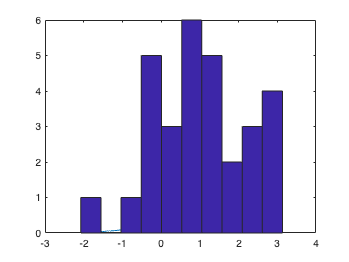

sigmaY = sqrt(varY); % entspricht std(yDiffIntervallComplete);
muY    = mean(yDiffIntervallComplete);
hold off;

plot(xi, normDist(xi, sigmaY, muY)); hold on;
hist(yDiffIntervallComplete);

% Theta-Theta
xi = [min(thetaDiffIntervallComplete):.001:max(thetaDiffIntervallComplete)];
varTheta = var(thetaDiffIntervallComplete)

varTheta = 2.8484e-04

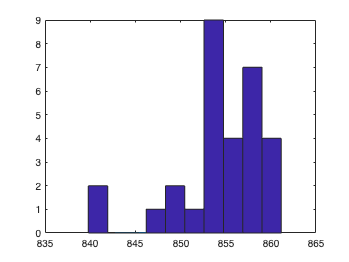

sigmaTheta = sqrt(varTheta);
muTheta    = mean(thetaDiffIntervallComplete);
hold off;

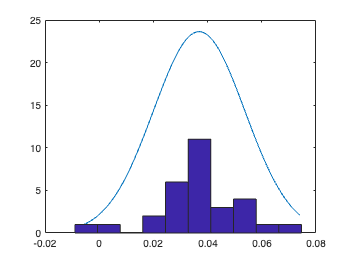

plot(xi, normDist(xi, sigmaTheta, muTheta)); hold on;
hist(thetaDiffIntervallComplete);


% OPTIONAL ENDE ++++++++++++++++++++++++++++

% ++++Kovarianzmatrix+++

%Erstellen Matrix aus Messungen
A = [xDiffIntervallComplete yDiffIntervallComplete thetaDiffIntervallComplete]

A = 30×3
   -0.3144  851.8886    0.0534
    0.1948  854.4017    0.0378
    1.3196  860.4916    0.0248
   -0.2834  854.4222    0.0377
    3.1130  857.6563    0.0181
   -0.4163  856.8714    0.0411
    3.1352  854.2228    0.0329
    0.3498  861.1538    0.0281
    0.8059  841.1788    0.0019
    0.7572  857.2319    0.0388



CovMat = cov(A)

CovMat = 3×3
    1.5214    0.3889    0.0002
    0.3889   26.0708   -0.0210
    0.0002   -0.0210    0.0003



filename(end-1:end) = []; %Entfernen der Messnummer aus Dateiname
save(filename, "CovMat", "xDiffIntervallComplete", "yDiffIntervallComplete", "thetaDiffIntervallComplete");
